## Time Series Forecasting Using Deep Learning

### Data read

clc; clear;

data_train = readtable('data/sales_train.csv');
data_test = readtable('data/test.csv');

head(data_train)

ans = 8×6 table
         date         date_block_num    shop_id    item_id    item_price    item_cnt_day
    ______________    ______________    _______    _______    __________    ____________

    {'02.01.2013'}          0             59        22154         999             1     
    {'03.01.2013'}          0             25         2552         899             1     
    {'05.01.2013'}          0             25         2552         899            -1     
    {'06.01.2013'}          0             25         2554        1709             1     
    {'15.01.2013'}          0             25         2555        1099             1     
    {'10.01.2013'}          0             25         2564         349             1     
    {'02.01.2013'}          0             25         2565         5

head(data_test)

ans = 8×3 table
    ID    shop_id    item_id
    __    _______    _______

    0        5        5037  
    1        5        5320  
    2        5        5233  
    3        5        5232  
    4        5        5268  
    5        5        5039  
    6        5        5041  
    7        5        5046  


### **Data grouping**

Group the data according to months and item_ids, sum by item sales for each group, then create a sales by months matrix for each item

[G, ID] = findgroups(data_train(:, 3:4));
sale_counts = splitapply(@(month, sale){count_sales(month, sale)}, data_train(:, 2), data_train(:, 6), G);
sale_counts = cell2mat(sale_counts);

sales = [ID table(sale_counts)];
head(sales)

ans = 8×3 table
    shop_id    item_id     sale_counts 
    _______    _______    _____________

       0         30       [1×34 double]
       0         31       [1×34 double]
       0         32       [1×34 double]
       0         33       [1×34 double]
       0         35       [1×34 double]
       0         36       [1×34 double]
       0         40       [1×34 double]
       0         42       [1×34 double]


### **Data standardization**

For a better fit and to prevent the training from diverging, standardize the training data to have zero mean and unit variance.

% mean and std. dev. for each item, not month
mu = mean(sale_counts.')';
sig = std(sale_counts.')';

sales_train_standardized = (sale_counts - mu) ./ sig;
sales_train_standardized(isnan(sales_train_standardized)) = 0;

### **Preparing predictors and responses**

To forecast the values of future time steps of a sequence, specify the  responses to be the training sequences with values shifted by one time  step. That is, at each time step of the input sequence, the LSTM network learns to predict the value of the next time step. The predictors are  the training sequences without the final time step

x_train = sales_train_standardized(:, 1:end-1);
y_train = sales_train_standardized(:, 2:end);

### **Defining LSTM network architecture**

group_height = height(ID);

num_inputs = group_height;
num_responses = group_height;
num_hidden_units = 75;

layers = [ ...
    sequenceInputLayer(num_inputs)
    lstmLayer(num_hidden_units)
    fullyConnectedLayer(num_responses)
    regressionLayer];

options = trainingOptions('adam', ...
    'ExecutionEnvironment',"gpu", ...
    'MaxEpochs',200, ...
    'InitialLearnRate',0.05, ...
    'LearnRateSchedule','piecewise', ...
    'MiniBatchSize',20, ...
    'LearnRateDropPeriod',50, ...
    'LearnRateDropFactor',0.5, ...
    'VerboseFrequency', 25, ...
    'Plots','training-progress' ...
    );

### **Training LSTM network**

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:02 |       630.16 |     198553.1 |          0.0500 |


|      25 |          25 |       00:00:35 |       133.94 |       8970.1 |          0.0500 |


|      50 |          50 |       00:01:09 |        44.44 |        987.4 |          0.0500 |


|      75 |          75 |       00:01:45 |        31.36 |        491.7 |          0.0250 |


|     100 |         100 |       00:02:22 |        47.99 |       1151.4 |          0.0250 |


|     125 |         125 |       00:02:56 |        22.72 |        258.1 |          0.0125 |


|     150 |         150 |       00:03:33 |        14.11 |         99.5 |          0.0125 |


|     175 |         175 |       00:04:08 |         4.72 |         11.2 |          0.0063 |


|     200 |         200 |       00:04:43 |         3.18 |          5.1 |          0.0063 |


|========================================================================================|


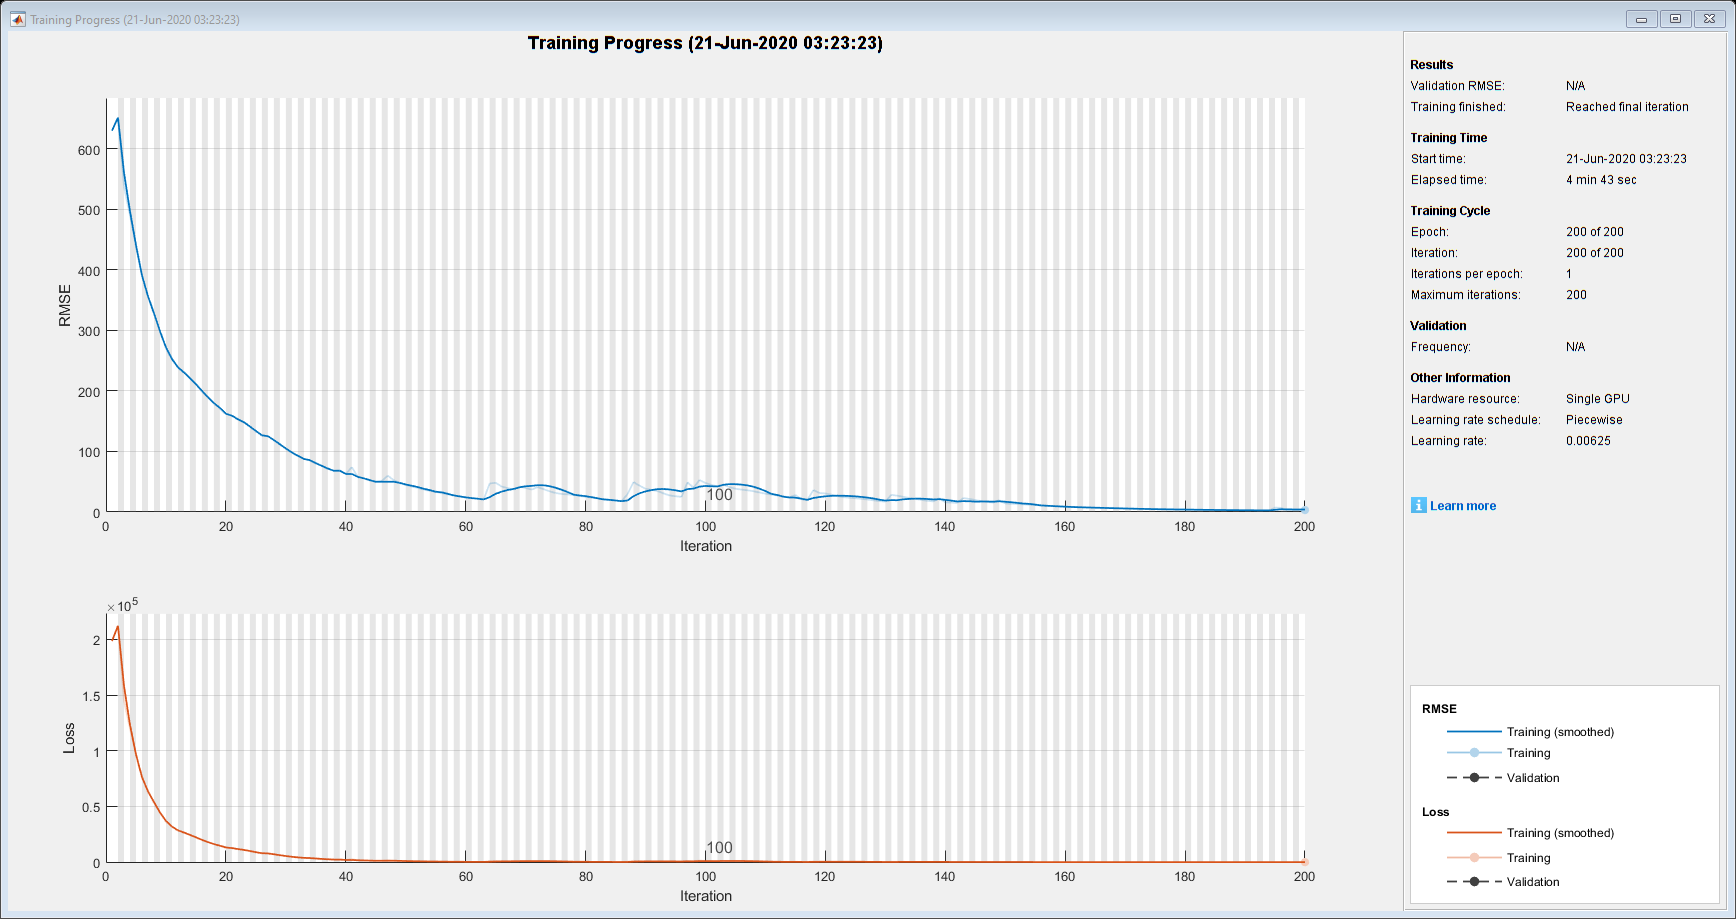

if isfile("model/net.mat")
    load net
else
    net = trainNetwork(x_train, y_train, layers, options);
    save('model/net.mat', 'net', '-v7.3');
end

### **Forecasting future time steps**

To initialize the network state, first predict on the training data `x_train`. Next, make the first prediction using the last time step of the training response `y_train(end)`.

% Initialize Net.
net = predictAndUpdateState(net, x_train);
[net, y_pred] = predictAndUpdateState(net, y_train(:, end));

% Predict next months sales
[net, pred] = predictAndUpdateState(net, y_pred);

pred = pred .* sig + mu;
pred_r = round(pred);

result = addvars(ID, sale_counts, pred_r);

### **Results**

result_sorted = sortrows(result, "pred_r", "descend");
head(result_sorted(:, [1 2 4]))